# SVM with Concentric Data

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads, partitions, and plots the data.

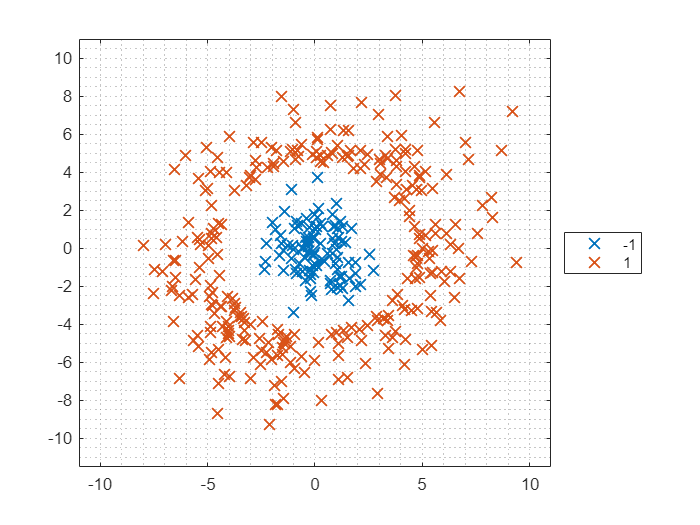

points = readtable("data\points.csv");
rng(123)
cvpt = cvpartition(points.group, "Holdout", 0.38);
trainPoints = points(training(cvpt), :);
testPoints = points(test(cvpt), :);
plotGroup(points, points.group, "x")

## Task 1

The training data set is in the `trainPoints` table with the response variable named `"group"`.

mdl = fitcsvm(trainPoints, "group", "KernelFunction", "polynomial");
mdlLoss = loss(mdl, testPoints)

mdlLoss = 0

Plot predicted groups.

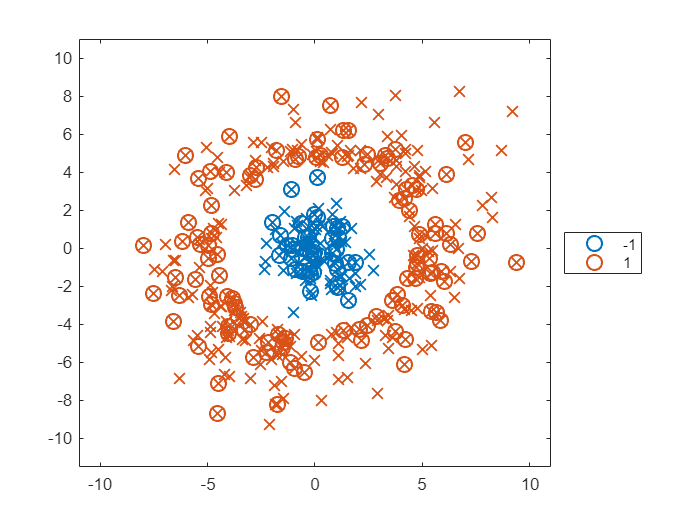

predGroups = predict(mdl, testPoints);
plotGroup(points, points.group, "x")
hold on
plotGroup(testPoints, predGroups, "o")
hold off

This function uses `gscatter` to create a formatted plot of grouped data.

function plotGroup(data, grp, mkr)
    validateattributes(data, "table", {'nonempty', 'ncols', 3})
    
    % Plot data by group
    colors = colororder;
    p = gscatter(data.x, data.y, grp, colors([1 2 4], :), mkr, 9);
    grid minor
    
    % Format plot
    [p.LineWidth] = deal(1.25);
    legend("Location", "eastoutside")
    xlim([-11 11])
    ylim([-11.5 11])
end